%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ACTSlab - Sapienza Universita di Roma
% Author: 2024 Camille LANFREDI 

% A more complex version where you can input the file. You are able to print 
% every channel impulse response, but the length of each pair must be equal 
% or it will not be detected and taken into account.
% To quit the bash, press 0
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Read the file and extract the data
file_path = ['L1_R2_CIRs_Ch_9.txt'];
[CIR_real_all, CIR_imag_all] = readCIRValuesFromMeasurments(file_path);

% Display the total number of pairs read
disp(['Total number of read CIR pairs: ', num2str(length(CIR_real_all))]);

Total number of read CIR pairs: 514


CIR number 1


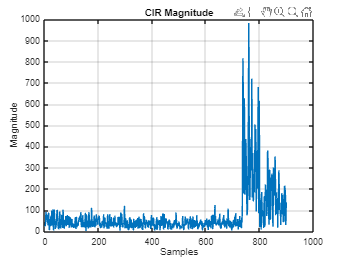

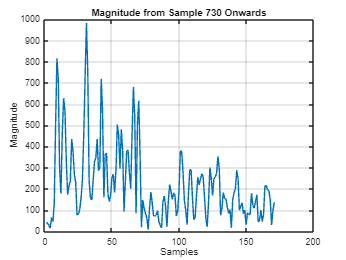

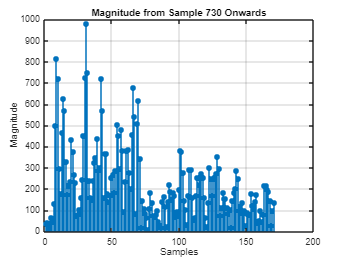


% Interactive bash
while true
    % Ask the user which CIR they want to display
    prompt = 'Enter the CIR number you want to display (1-1087) or 0 to exit: ';
    CIRNumber = input(prompt);
    
    if CIRNumber == 0 % To quit the bash, press 0
        break;
    end

    % Display the values for the selected CIR
    if CIRNumber > 0 && CIRNumber <= length(CIR_real_all)
        disp(['CIR number ', num2str(CIRNumber)]);
        % disp('Real Values:');
        % disp(CIR_real_all{CIRNumber}');
        % disp('Imag Values:');
        % disp(CIR_imag_all{CIRNumber}');
        
        % Calculate the magnitude of the CIR
        CIR_real = CIR_real_all{CIRNumber}';
        CIR_imag = CIR_imag_all{CIRNumber}';
        CIR_magnitude = sqrt(CIR_real.^2 + CIR_imag.^2);
        
        % Display the magnitude of the CIR
        figure;
        plot(CIR_magnitude);
        title('CIR Magnitude');
        xlabel('Samples');
        ylabel('Magnitude');
        grid on;
        
        % Display the magnitude of the CIR from sample 730 onwards
        figure;
        plot(CIR_magnitude(730: end));
        title('Magnitude from Sample 730 Onwards');
        xlabel('Samples');
        ylabel('Magnitude');
        grid on;

        % Display the stem plot of the magnitude from sample 730 onwards
        figure;
        stem(CIR_magnitude(730:end), 'filled');
        title('Magnitude from Sample 730 Onwards');
        xlabel('Samples');
        ylabel('Magnitude');
        grid on;

    else
        disp('Invalid CIR number.');
    end
end